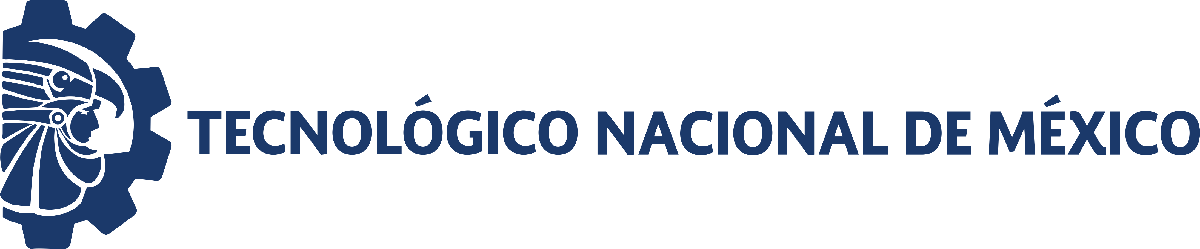                                 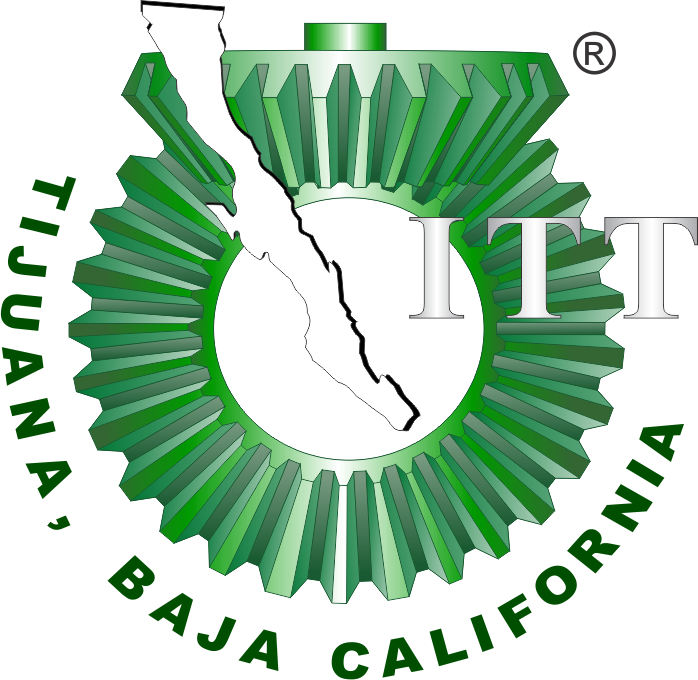

# Final Proyect: Digital Twin

**Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## General Information

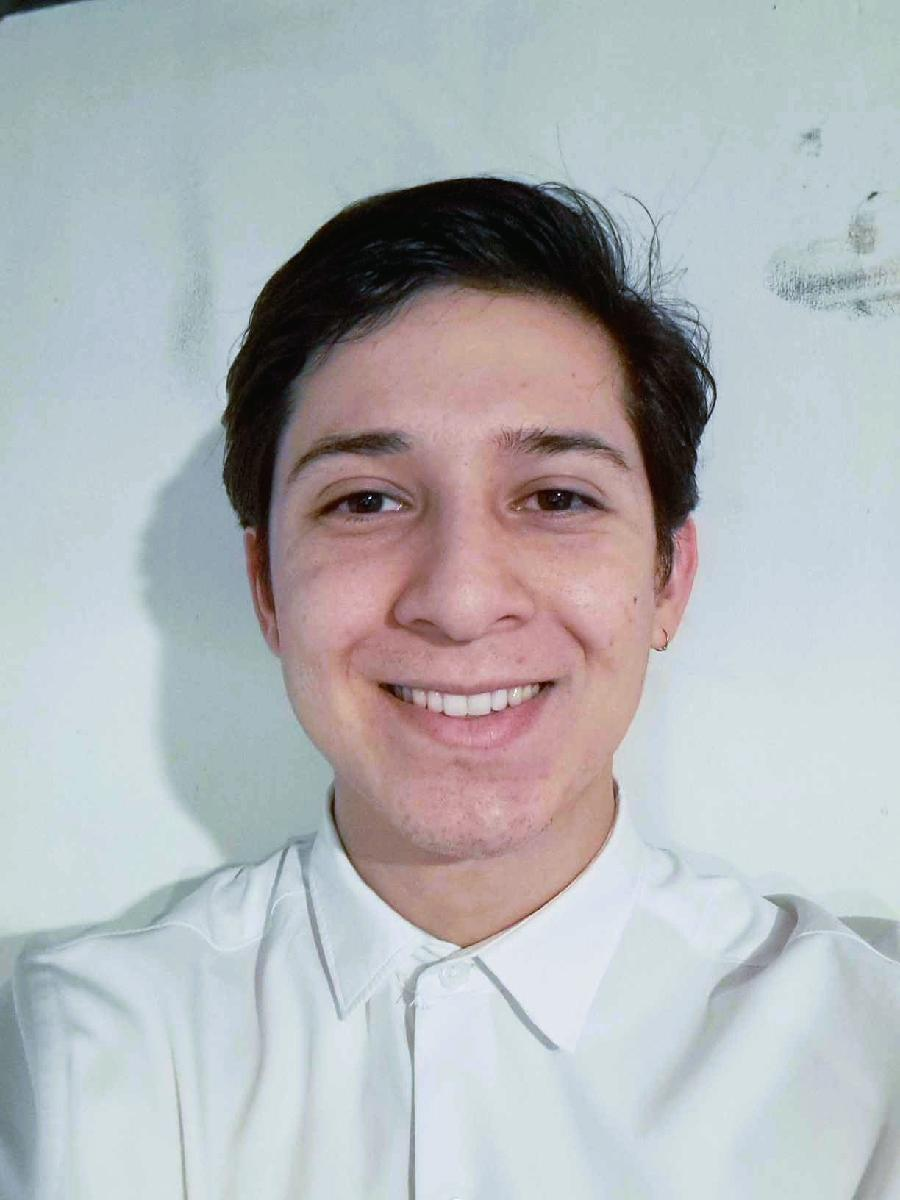

Nombre del alumno: **Jesus Zamora Cervantes**

Número de control: **21212185**

Correo institucional: **l21212185@tectijuana.edu.mx**

Carrera: **Ingeniería Biomédica**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Simulation data

clc; clear; close all; warning('off','all')


filename = 'rawdata.csv';
sys = readmatrix(filename); 

t = round(sys(:,1));  
x1 = sys(:,2); y1 = sys(:,3); z1 = sys(:,4);

T = array2table([t, x1, y1, z1], ...
    'VariableNames', {'Tiempo', 'x1(t)', 'y1(t)', 'z1(t)', ...
                      });
disp(T)

    Tiempo    x1(t)     y1(t)     z1(t) 
    ______    ______    ______    ______

       0       5.596      14.8    109.84
       7      11.975    12.135    100.18
      14      29.188     7.048    68.925
      21      48.982     3.126    29.523
      28       57.75     1.786     9.812
      35      60.279     1.431     4.976
      42      61.764     1.158     3.581
      49      62.522     0.881     3.064
      56      62.732     0.606      2.91
      63       62.91     0.321     2.804
      70      62.881     0.114      2.73



## Raw data plot

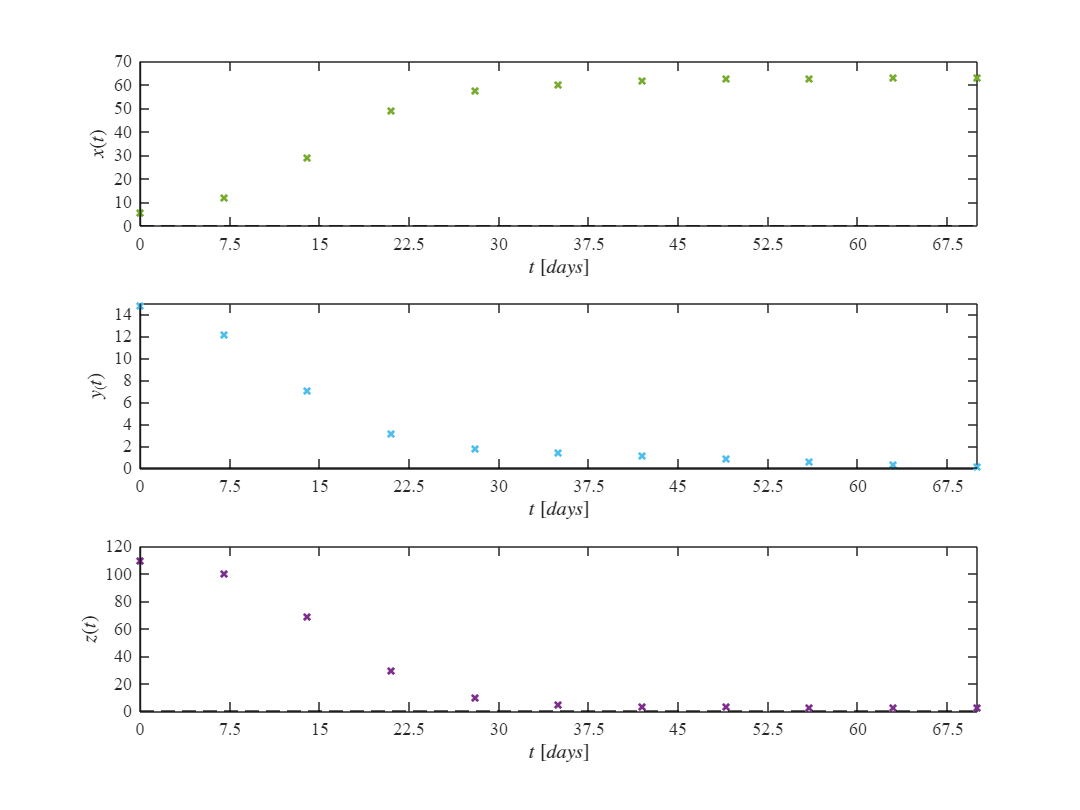

plotGraficas(t,x1,y1,z1) 
exportgraphics(gcf, '1. Datos_en_crudo.pdf', 'ContentType', 'vector');

## Smooth data

sys = readmatrix('rawdata.csv');
t = sys(:,1);
x1 = sys(:,2);
y1 = sys(:,3);
z1 = sys(:,4);

xo =smoothdata(x1);
yo =smoothdata(y1);
zo =smoothdata(z1);


Ts = array2table([t, xo, yo, zo], ...
    'VariableNames', {'Time', 'x(t)', 'y(t)', 'z(t)', ...
                      });
disp(Ts)

    Time     x(t)      y(t)       z(t) 
    ____    ______    _______    ______

      0     8.7855     13.468    105.01
      7     15.586     11.328     92.98
     14     23.935     7.4363    77.116
     21     36.974     3.9867    52.109
     28      49.05     2.1143    28.309
     35     57.194     1.4583    11.973
     42     60.579     1.1567    5.3582
     49     61.824    0.88167    3.6327
     56     62.482    0.60267    3.0897
     63     62.761      0.347     2.877
     70     62.841     0.2175    2.8147



writetable(Ts, 'data_smooth.csv');
plotGraficas1(t,xo,yo,zo);
exportgraphics(gcf, '2. Datos_suavizados.pdf', 'ContentType', 'vector');

## Smooth data plot

## Nonlinear Regression

P0 = [0.0009, 0.0040, 0.0150, 0.0001, 0.0050, 0.050];
[mdl, xa, ya, za ] = Model1 (t, xo, yo ,zo, P0); plotModel1(t,[xo,xa],[yo,ya],[zo,za]);


Sample size (n): 11
Parameters to be estimated (pars): 6
Degrees of freedom: 27
Significance level (alpha): 0.05
t-Student value: 2.0518
Adjusted R-squared: 0.99624
Corrected AIC (n/pars < 40): 32.0573 

    Parameters     Estimate         SE           MoE                  CI95                pvalue  
    __________    __________    __________    __________    ________________________    __________

        p1        0.00095911    0.00011849    0.00024312    0.00071599     0.0012022    1.0724e-08
        p2         0.0010805     0.0011504     0.0023604     0.0012799     0.0034409       0.35592
        p3         0.0072501      0.033927      0.069612      0.062362      0.076862       0.83239
        p4        2.7553e-05    2.4225e-05    4.9706e-05    2.2153e-05    7.7259e-05       0.26

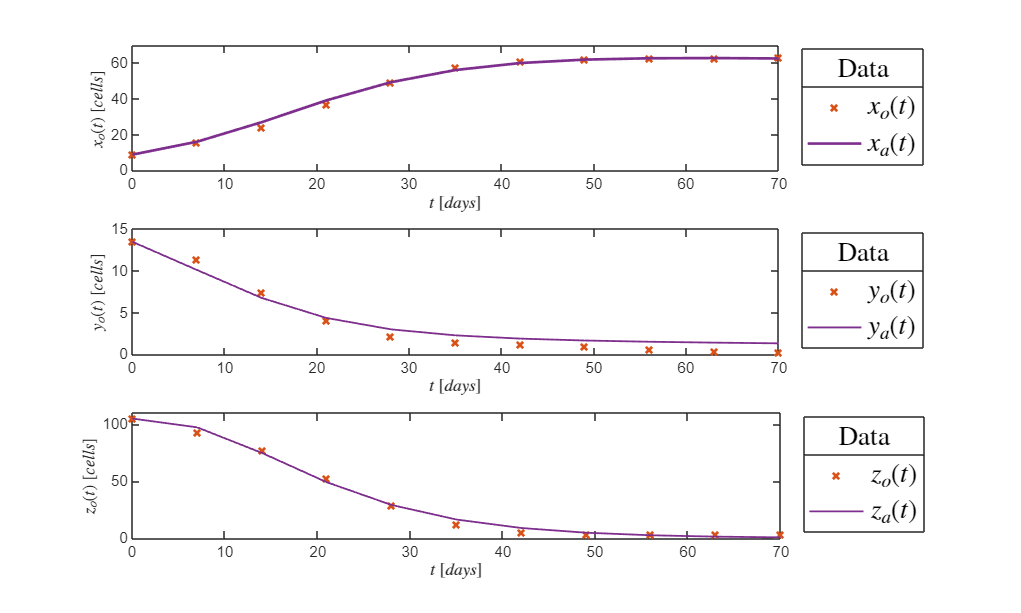

exportgraphics(gcf, '3. Algoritmo_de_RNL.pdf', 'ContentType', 'vector');

## Jacobian Matrix and Equilibrium Points

syms x y z p1 p2 p3 p4 p5 p6 
          dx = p1*x*z - p2*x*y;
          dy = -p3*y - p4*x*y*z;
          dz = p5*y*z - p6*z;

J = jacobian([dx,dy,dz],[x,y,z]);
fprintf('Jacobian matrix of the Lotka-Volterra system: '); disp(J)

Jacobian matrix of the Lotka-Volterra system: 

$$\left(\begin{array}{ccc} p_{1}\,z-p_{2}\,y & -p_{2}\,x & p_{1}\,x\\ -p_{4}\,y\,z & -p_{3}-p_{4}\,x\,z & -p_{4}\,x\,y\\ 0 & p_{5}\,z & p_{5}\,y-p_{6} \end{array}\right)$$

edos = solve([dx,dy,dz],[x,y,z]);
fprintf(['the system has ', num2str(length(edos.x)), ' equilibrium points.'])

the system has 2 equilibrium points.

X0 = edos.x(1); Y0 = edos.y(1); Z0 = edos.z(1);
X1 = edos.x(2); Y1 = edos.y(2); Z1 = edos.z(2);

syms x0 y0 z0 x1 y1 z1 
fprintf('Equilibrium points of the Lotka-Volterra system: '); 

Equilibrium points of the Lotka-Volterra system: 

disp([x0,y0,z0,X0,Y0,Z0]); disp([x1,y1,z1,X1,Y1,Z1]); 

$$\left(\begin{array}{cccccc} x_{0} & y_{0} & z_{0} & 0 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccccc} x_{1} & y_{1} & z_{1} & -\frac{p_{1}\,p_{3}\,p_{5}}{p_{2}\,p_{4}\,p_{6}} & \frac{p_{6}}{p_{5}} & \frac{p_{2}\,p_{6}}{p_{1}\,p_{5}} \end{array}\right)$$


eq1 = dx == 0;
eq2 = dy == 0;
eq3 = dz == 0;

equilibria = solve([eq1, eq2, eq3], [x, y, z]);
for i = 1:length(equilibria.x)
    xe(i,1) = simplify(equilibria.x(i));
    ye(i,1) = simplify(equilibria.y(i));
    ze(i,1) = simplify(equilibria.z(i));

    fprintf('Equilibrium point %d:\n', i)
    fprintf('x%d = %s\n', i, char(xe(i,1)));
    fprintf('y%d = %s\n', i, char(ye(i,1)));
    fprintf('z%d = %s\n\n', i, char(ze(i,1)));
end

Equilibrium point 1:


x1 = 0


y1 = 0


z1 = 0



Equilibrium point 2:


x2 = -(p1*p3*p5)/(p2*p4*p6)


y2 = p6/p5


z2 = (p2*p6)/(p1*p5)



p1 = 0.00117;   p2 = 0.00318;   p3 =  0.0118;
p4 = 4.22e-5;   p5 = 0.00631;   p6 = 0.0923;

    x1 = 0;
    y1 = 0;
    z1 = 0;

    x2 = -(p1*p3*p5)/(p2*p4*p6);
    y2 = p6/p5;    
    z2 = (p2*p6)/(p1*p5);

    xe = [x1; x2]; ye = [y1; y2]; ze = [z1; z2];
    Eqs = array2table([xe, ye, ze], 'VariableNames', {'x*','y*','z*'});
    disp(Eqs)

      x*         y*        z*  
    _______    ______    ______

          0         0         0
    -7.0332    14.628    39.757



## Local Stability

close all; warning('off','all')
p1 = 0.00095911; 
p2 = 0.0010805;  
p3 = 0.0072501;  
p4 = 2.7553e-05; 
p5 = 0.0077425;  
p6 = 0.10239;

syms x y z
    dx = p1*x*z - p2*x*y;
    dy = -p3*y - p4*x*y*z;
    dz = p5*y*z - p6*z;
edos = solve([dx,dy,dz],[x,y,z]);
x0 = double(edos.x(1)); y0 = double(edos.y(1)); z0 = double(edos.z(1));
x1 = double(edos.x(2)); y1 = double(edos.y(2)); z1 = double(edos.z(2));


clear x y z
x = [x0;x1]; y = [y0;y1]; z= [z0;z1];
var = {'(x0,y0,z0) '; '(x1,y1,z1) '};
Equilibria = table(x,y,z,'RowNames',var);
Equilibria.Properties.VariableNames = {'xe','ye','ze'};
fprintf('Equilibrium points of the system:\n'); disp(Equilibria)

Equilibrium points of the system:
                    xe         ye        ze  
                  _______    ______    ______

    (x0,y0,z0)          0         0         0
    (x1,y1,z1)    -17.662    13.224    14.898



L = zeros(length(x),3);
for i = 1:length(x)
     J = [ (p1*z(i) - p2*y(i)), (-p2*x(i)), (p1*x(i));
          (-p4*y(i)*z(i)), (-p3 - p4*x(i)*z(i)), (-p4*x(i)*y(i));
          0, (p5*z(i)), (p5*y(i) - p6) ];
      L(i,:) = eig(J);
end
L1 = L(:,1); L2 = L(:,2); L3 = L(:,3);
Lambdas = table(L1,L2,L3,'RowNames',var);
disp('Eigen values of the Jacobian matrix evaluated at each equilibrium point:'); disp(Lambdas);

Eigen values of the Jacobian matrix evaluated at each equilibrium point:
                           L1                      L2                 L3   
                  ____________________    _____________________    ________

    (x0,y0,z0)     -0.10239+0i            -0.0072501+0i                   0
    (x1,y1,z1)    -0.015636+0.0097319i     -0.015636-0.0097319i    0.031272



minx = min(xo);
maxx = max(xo);
xonormalizado = (xo - minx) / (maxx - minx);
miny = min(yo);
maxy = max(yo);
yonormalizado = (yo - miny) / (maxy - miny);
minz = min(zo);
maxz = max(zo);
zonormalizado = (zo - minz) / (maxz - minz);

## Prediction 2t

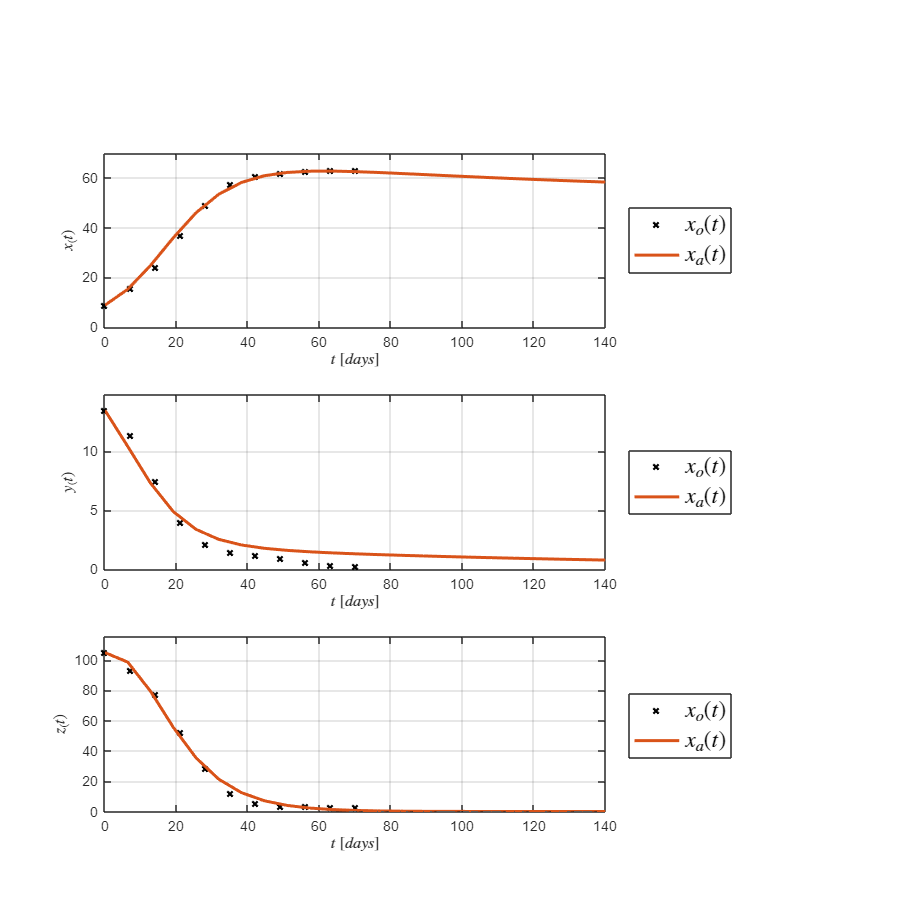

p1ajustado = 0.00095911;
p2ajustado = 0.0010805;
p3ajustado = 0.0072501;
p4ajustado = 2.7553e-05;
p5ajustado = 0.0077425;
p6ajustado = 0.10239;


toriginalmax = max(t); 
tpredict = 0:(toriginalmax/length(t)):1000; 
initialconditions = [xo(1); yo(1); zo(1)];
options = odeset('RelTol',1e-6,'AbsTol',1e-9);
[tsol, xsol] = ode45(@(t, X) myODESystem(t, X, ...
                                    p1ajustado, p2ajustado, p3ajustado, ...
                                    p4ajustado, p5ajustado, p6ajustado), ...
                       tpredict, initialconditions, options);
xpredict = xsol(:,1);
ypredict = xsol(:,2);
zpredict = xsol(:,3);

 plotprediction(t, xo, yo, zo, tsol, xpredict, ypredict, zpredict);
 exportgraphics(gcf, '5. Predicción_a_2t.pdf', 'ContentType', 'vector');

## **Conclusion.**

The extended Lotka-Volterra model, although not all of its parameters were individually significant, achieved an excellent fit to the smoothed data, validating its ability to represent population dynamics. Analysis of the equilibrium points revealed two scenarios. The point (0,0,0) represents the extinction of all populations, a biologically plausible outcome. However, the second equilibrium point yielded a negative value for population x*, indicating a biological impossibility. This suggests that, under the modeled interactions, the system does not tend toward a stable and positive state of coexistence for the three populations. The instability of this point, confirmed by a positive eigenvalue, reinforces that the system would move away from it under any perturbation, leading to continuous dynamics of population change. Long-term simulations (up to 1000 days) illustrate this instability, showing that two populations (y(t) and z(t)) tend toward extinction, while one (x(t)) stabilizes, suggesting exclusion or dominance dynamics. The formulated mathematical model demonstrated high validity in its ability to approximate the experimental data and predict its short-term dynamics. The extremely high Rfit is the main evidence that the model faithfully reproduces the observed variability. The fitted parameters, although not all individually statistically significant, together allow the system of differential equations to replicate biological behavior.

The predictive capacity of the model is a fundamental characteristic of this digital twin. By integrating the system of ODEs with the fitted parameters, the model allows the simulation and projection of future population dynamics beyond the original data range. This extrapolation, while not guaranteeing perfect accuracy over the very long term without additional validation, provides a robust tool for understanding and anticipating trends in the biological system over relevant timeframes.

In conclusion, this digital twin offers an accurate representation of the biological system, validated by its outstanding data fit and predictive capacity. Although the biological inviability of some equilibrium points indicates a lack of coexistence stability in the model, its usefulness lies in the simulation and anticipation of population dynamics.

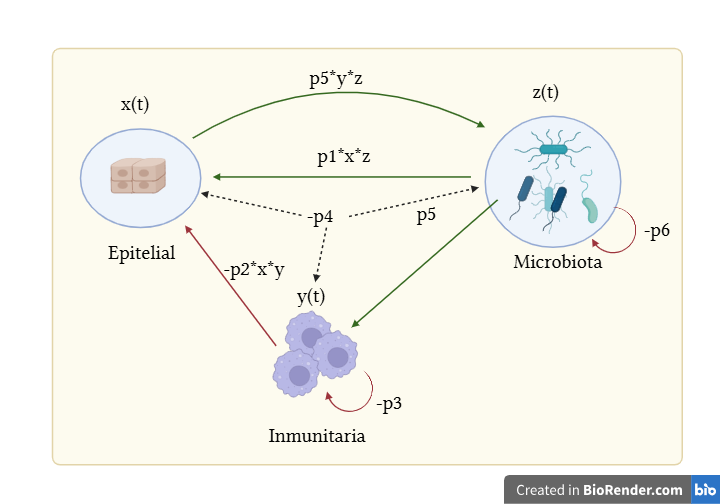

## Functions (Plots)

function plotGraficas(t, x1, y1, z1)
    figure('Position', [100, 100, 800, 600]);  
    rd = [0.6350 0.0780 0.1840];
    cy = [0.3010 0.7450 0.9330];
    gr = [0.4660 0.6740 0.1880];
    pr = [0.4940 0.1840 0.5560];
    or = [0.8500 0.3250 0.0980];
 
    subplot(3,1,1)
    set(gca,'FontName','Times New Roman','FontSize',10)
    hold on; box on; grid off;
    plot(t, x1, 'x', 'MarkerSize',5, 'LineWidth',1.5, 'Color', gr)
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$x(t)$','Interpreter','latex')
    xlim([0 70]); xticks(0:7.5:70)
    ylim([0 70]); yticks(0:10:70)
    xline(0,'','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')
    title('','Interpreter','latex')

   
    subplot(3,1,2)
    set(gca,'FontName','Times New Roman','FontSize',10)
    hold on; box on; grid off;
    plot(t, y1, 'x', 'MarkerSize',5, 'LineWidth',1.5, 'Color', cy)
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$y_(t)$','Interpreter','latex')
    xlim([0 70]); xticks(0:7.5:70)
    ylim([0 15]); yticks(0:2:15)
    xline(0,'','LineWidth',1,'Color','k')
    yline(0,'','LineWidth',1,'Color','k')
    title('','Interpreter','latex')

    subplot(3,1,3)
    set(gca,'FontName','Times New Roman','FontSize',10)
    hold on; box on; grid off;
    plot(t, z1, 'x', 'MarkerSize',5, 'LineWidth',1.5, 'Color', pr)
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$z(t)$','Interpreter','latex')
    xlim([0 70]); xticks(0:7.5:70)
    ylim([0 120]); yticks(0:20:120)
    xline(0,'','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')
    title('','Interpreter','latex')
end 

function plotGraficas1(t, xo, yo, zo)
figure('Position', [100, 100, 800, 600]);  
    rd = [0.6350 0.0780 0.1840];
    cy = [0.3010 0.7450 0.9330];
    gr = [0.4660 0.6740 0.1880];
    pr = [0.4940 0.1840 0.5560];
    or = [0.8500 0.3250 0.0980];
 
    subplot(3,1,1)
    set(gca,'FontName','Times New Roman','FontSize',10)
    hold on; box on; grid off;
    plot(t, xo, 'x', 'MarkerSize',5, 'LineWidth',1.5, 'Color', gr)
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$x(t)$','Interpreter','latex')
    xlim([0 70]); xticks(0:7.5:70)
    ylim([0 70]); yticks(0:10:70)
    xline(0,'','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')
    title('','Interpreter','latex')

   
    subplot(3,1,2)
    set(gca,'FontName','Times New Roman','FontSize',10)
    hold on; box on; grid off;
    plot(t, yo, 'x', 'MarkerSize',5, 'LineWidth',1.5, 'Color', cy)
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    xlim([0 70]); xticks(0:7.5:70)
    ylim([0 15]); yticks(0:2:15)
    xline(0,'','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')
    title('','Interpreter','latex')

    subplot(3,1,3)
    set(gca,'FontName','Times New Roman','FontSize',10)
    hold on; box on; grid off;
    plot(t, zo, 'x', 'MarkerSize',5, 'LineWidth',1.5, 'Color', pr)
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$z(t)$','Interpreter','latex')
    xlim([0 70]); xticks(0:7.5:70)
    ylim([0 120]); yticks(0:20:120)
    xline(0,'','LineWidth',1,'Color','k')
    yline(0,'--','LineWidth',1,'Color','k')
    title('$','Interpreter','latex')
end

function plotModel1(t,x,y,z)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,12])
    set(gca,'FontName','Times New Roman')
    fontsize(12,'points')
    c1 = [0.8500, 0.3250, 0.0980];
    c2 = [0.4940, 0.1840, 0.5560]; 
    c3 = [0.4660, 0.6740, 0.1880]; 

    subplot(3,1,1)
    hold on; box on; grid off;
    plot(t,x(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',c1)
    plot(t,x(:,2),'-','LineWidth',1.5,'Color',c2)
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$x_o(t)$ $[cells]$','Interpreter','latex')
    L = legend ('$x_o(t)$','$x_a(t)$');
    set(L,'Interpreter','latex','FontSize',15,'Location','EastOutside','Box','On')
    title(L,'Data')
    xlim([min(t) max(t)])
    ylim([0 70])

    subplot(3,1,2)
    hold on; box on; grid off;
    plot(t,y(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',c1)
    plot(t,y(:,2),'-','LineWidth',1,'Color',c2)
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$y_o(t)$ $[cells]$','Interpreter','latex')
    L = legend ('$y_o(t)$','$y_a(t)$');
    set(L,'Interpreter','latex','FontSize',15,'Location','EastOutside','Box','On')
    title(L,'Data')
    xlim([min(t) max(t)])
    ylim([0 15])

    subplot(3,1,3)
    hold on; box on; grid off;
    plot(t,z(:,1),'x','MarkerSize',5,'LineWidth',1.5,'Color',c1)
    plot(t,z(:,2),'-','LineWidth',1,'Color',c2)
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$z_o(t)$ $[cells]$','Interpreter','latex')
    L = legend ('$z_o(t)$','$z_a(t)$');
    set(L,'Interpreter','latex','FontSize',15,'Location','EastOutside','Box','On')
    title(L,'Data')
    xlim([min(t) max(t)])
    ylim([0 110])
end

function plotNormalizadas(t, xo_normalizado, yo_normalizado, zo_normalizado)
figure('Position', [100, 100, 800, 600]);

cy = [0.3010 0.7450 0.9330]; 
gr = [0.4660 0.6740 0.1880]; 
pr = [0.4940 0.1840 0.5560]; 

subplot(3,1,1);
set(gca,'FontName','Times New Roman','FontSize',10);
hold on; box on; grid off;
plot(t, xo_normalizado, '-', 'MarkerSize', 5, 'LineWidth', 1.5, 'Color', gr);
xlabel('$t$ $[days]$', 'Interpreter', 'latex');
ylabel('$x_{norm}(t)$', 'Interpreter', 'latex'); 
xlim([0 70]); xticks(0:7.5:70);
ylim([0 1]); yticks(0:0.2:1); 
xline(0, '', 'LineWidth', 1, 'Color', 'k');
yline(0, '--', 'LineWidth', 1, 'Color', 'k');
title('', 'Interpreter', 'latex'); 

subplot(3,1,2);
set(gca,'FontName','Times New Roman','FontSize',10);
hold on; box on; grid off;
plot(t, yo_normalizado, '-', 'MarkerSize', 5, 'LineWidth', 1.5, 'Color', cy); 
xlabel('$t$ $[days]$', 'Interpreter', 'latex');
ylabel('$y_{norm}(t)$', 'Interpreter', 'latex'); 
xlim([0 70]); xticks(0:7.5:70);
ylim([0 1]); yticks(0:0.2:1); 
xline(0, '', 'LineWidth', 1, 'Color', 'k');
yline(0, '--', 'LineWidth', 1, 'Color', 'k');
title('', 'Interpreter', 'latex'); 

subplot(3,1,3);
set(gca,'FontName','Times New Roman','FontSize',10);
hold on; box on; grid off;
plot(t, zo_normalizado, '-', 'MarkerSize', 5, 'LineWidth', 1.5, 'Color', pr); 
xlabel('$t$ $[days]$', 'Interpreter', 'latex');
ylabel('$z_{norm}(t)$', 'Interpreter', 'latex'); 
xlim([0 70]); xticks(0:7.5:70);
ylim([0 1]); yticks(0:0.2:1); 
xline(0, '', 'LineWidth', 1, 'Color', 'k');
yline(0, '--', 'LineWidth', 1, 'Color', 'k');
title('', 'Interpreter', 'latex'); 

sgtitle('', 'Interpreter', 'latex', 'FontSize', 14); 

end

function plotprediction(t, xo, yo, zo, t_sol, x_predict, y_predict, z_predict)

figure('Position', [100, 100, 800, 800]);

c_original = [0 0 0];
c_predict = [0.8500 0.3250 0.0980];

subplot(3,1,1);
hold on; box on; grid on;
plot(t, xo, 'x', 'MarkerSize', 5, 'LineWidth', 1.5, 'Color', c_original);
plot(t_sol, x_predict, '-', 'LineWidth', 2, 'Color', c_predict);
xlabel('$t$ $[days]$', 'Interpreter', 'latex');
ylabel('$x_(t)$', 'Interpreter', 'latex');
title('', 'Interpreter', 'latex'); 
L = legend ('$x_o(t)$','$x_a(t)$');
    set(L,'Interpreter','latex','FontSize',15,'Location','EastOutside','Box','On')
xlim([0 140]); 

ylim_x_min = 0;
ylim_x_max = max(max(xo), max(x_predict)); 
if ylim_x_max < 70 
    ylim_x_max = 70;
end
ylim([ylim_x_min ylim_x_max]);


subplot(3,1,2);
hold on; box on; grid on;
plot(t, yo, 'x', 'MarkerSize', 5, 'LineWidth', 1.5, 'Color', c_original);
plot(t_sol, y_predict, '-', 'LineWidth', 2, 'Color', c_predict);
xlabel('$t$ $[days]$', 'Interpreter', 'latex');
ylabel('$y_(t)$', 'Interpreter', 'latex');
title('', 'Interpreter', 'latex'); 
L = legend ('$x_o(t)$','$x_a(t)$');
    set(L,'Interpreter','latex','FontSize',15,'Location','EastOutside','Box','On')
xlim([0 140]); 
ylim_y_min = 0;
ylim_y_max = max(yo)*1.1;
if ylim_y_max < 1 
    ylim_y_max = 1;
end
ylim([ylim_y_min ylim_y_max]);


subplot(3,1,3);
hold on; box on; grid on;
plot(t, zo, 'x', 'MarkerSize', 5, 'LineWidth', 1.5, 'Color', c_original);
plot(t_sol, z_predict, '-', 'LineWidth', 2, 'Color', c_predict);
xlabel('$t$ $[days]$', 'Interpreter', 'latex');
ylabel('$z_(t)$', 'Interpreter', 'latex');
title('', 'Interpreter', 'latex'); 
L = legend ('$x_o(t)$','$x_a(t)$');
    set(L,'Interpreter','latex','FontSize',15,'Location','EastOutside','Box','On')
xlim([0 140]); 
ylim_z_min = 0;
ylim_z_max = max(zo)*1.1;
if ylim_z_max < 1 
    ylim_z_max = 1;
end
ylim([ylim_z_min ylim_z_max]);


sgtitle('', 'Interpreter', 'latex', 'FontSize', 14); 

end

## Functions (Fitting_model)

function [mdl,xa,ya,za] = Model1(to,xo,yo,zo,P0)
    x0 = xo(1); y0 = yo(1); z0 = zo(1);
    to = [to;to;to];
    fo = [xo;yo;zo];

    function fi = model(p,t)
        p1 = p(1); p2 = p(2);
        p3 = p(3); p4 = p(4); 
        p5 = p(5); p6 = p(6);
      
       
        dt = 1E-3;
        t = reshape (t,[],3); t = t(:,1);
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(n+1,1); x(1) = x0;
        y = zeros(n+1,1); y(1) = y0;
        z = zeros(n+1,1); z(1) = z0;

        for i = 1:n
            [fx,fy,fz] = f(x(i),y(i),z(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            zn = z(i) + fz*dt;
            [fxn,fyn,fzn] = f(xn,yn,zn);

            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
            z(i+1) = z(i) + (fz + fzn)*dt/2;
        end

        function [dx,dy,dz] = f(x,y,z)
            dx = p1*x*z - p2*x*y;
            dy = -p3*y - p4*x*y*z;
            dz = p5*y*z - p6*z;
        end 
        
        xi = zeros(length(t),1);
        yi = zeros(length(t),1);
        zi = zeros(length(t),1);

        for j = 1:length(t)
            k = abs(time-t(j)) < 1E-9;
            xi(j) = x(k);
            yi(j) = y(k);
            zi(j) = z(k);
        end

        fi = [xi;yi;zi];
    end

    mdl = fitnlm(to,fo,@model,P0);

    fa = mdl.Fitted;
    fn = reshape(fa,[],3);
    xa = fn(:,1); ya = fn(:,2); za = fn(:,3);

    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95OG = coefCI(mdl,alpha);
    CI95 = abs(CI95OG);
    dof = mdl.DFE;
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Parameters = ['p1';'p2';'p3';'p4';'p5';'p6'];
    Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);

    fprintf(['\nSample size (n): ', num2str(numel(xo))]) 
    fprintf(['\nParameters to be estimated (pars): ', num2str(numel(P0))])
    fprintf(['\nDegrees of freedom: ', num2str(dof)])
    fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
    fprintf(['\nt-Student value: ', num2str(tval)])
    fprintf(['\nAdjusted R-squared: ', num2str(mdl.Rsquared.Adjusted)])
    fprintf(['\nCorrected AIC (n/pars < 40): 32.0573 ','\n\n'])
    disp(Results)

end

## Prediction 2t

function dxdt = myODESystem(t, X, p1, p2, p3, p4, p5, p6)
x = X(1);
y = X(2);
z = X(3);
dx = p1*x*z - p2*x*y;
dy = -p3*y - p4*x*y*z;
dz = p5*y*z - p6*z;
dxdt = [dx; dy; dz];
end